# MATLAB Fundamentals

## 1. Desktop Basics.

When you start MATLAB, the desktop appears in its default layout. The desktop includes these areas:

Files panel — Access your files.

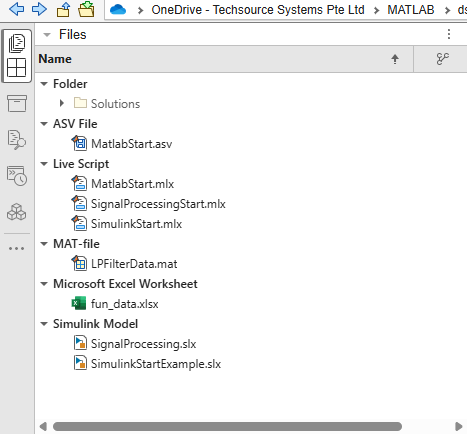

Workspace panel — Explore data that you create or import from files.

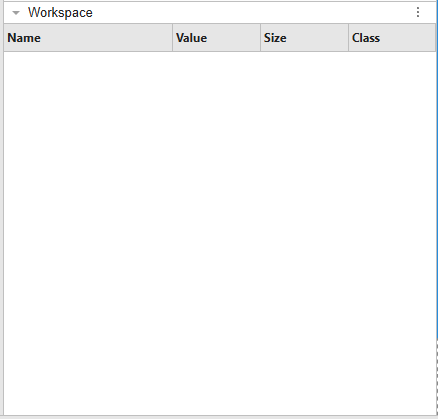

Command Window — Enter commands at the command line, indicated by the prompt (`>>`).

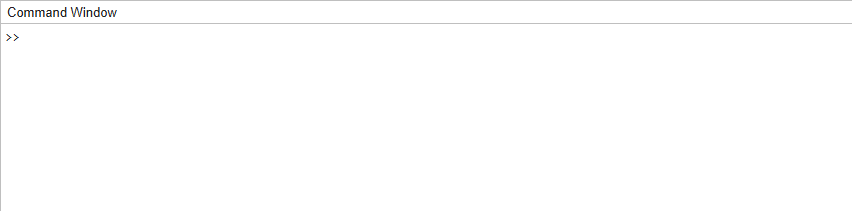

In the Live Editor, you can create live scripts that show output together with the code that produced it. 

Add formatted text, equations, images, and hyperlinks to enhance your narrative, and share the live script with others as an interactive document.

To run the code in a section, go to the **Live Editor** tab and click the **Run Section** button

## 2. Variables and Data Types.

MATLAB stores values in variables. Variable names must start with a letter and can contain letters, numbers, and underscores.

% Variables
x = 

x = 5

% Variable with semicolon
y = 
% String Variable
name = 

If you end a statement with a semicolon, MATLAB performs the computation, but suppresses the display of output.

% Value not assigned to a variable
sin(x)

ans = -0.9589

When you do not specify an output variable, MATLAB uses the variable `ans`, short for *answer*, to store the results of your calculation.

The variable's class is also stated in the Workspace.

## 3. Complex Number.

Complex numbers are fundamental in engineering and science for representing signals that have both magnitude and phase. In MATLAB, complex numbers are stored using `i` or `j` as the imaginary unit.

% Complex number
z = 

z =    1.0000 + 2.0000i   3.0000 + 4.0000i


% Magnitude % abs
z_abs = 

z_abs =     2.2361    5.0000


% Phase in radians % angle
z_phase = 

z_phase =     1.1071    0.9273


% In-phase component % real
z_real = 

z_real =      1     3


% Quadrature component % imag
z_imag = 

z_imag =      2     4


## 4. Vectors and Matrices.

MATLAB is designed for numeric arrays. Create a row vector, column vector and a matrix.

% row vector
row_Vec = 

row_Vec =      6     7     8     9    10


% column vector
col_Vec = 

col_Vec =     10
    20
    30
    40
    50


% matrix
mat_A = 

mat_A =      1     2     3
     4     5     6
     7     8     9


Compute a new matrix by using built-in matrix operations transpose.

% transpose
mat_A_trans = 

mat_A_trans =      1     4     7
     2     5     8
     3     6     9


## 5. Indexing and Slicing.

Get individual values or sections from arrays using parentheses.

% first index
first_Val = 

first_Val = 6

% 3rd row 2nd column index
third_Row_Second_Col = 

third_Row_Second_Col = 8

% sub matrix
sub_Mat = 

sub_Mat =      2     3
     5     6


Change one element in the matrix.

% matrix element change
mat_A(2, 3) = 

mat_A =      1     2     3
     4     5    12
     7     8     9


All in a row or column.

% all row vector
mat_A_row = 

mat_A_row =      4     5    12


% all column vector
mat_A_col = 

mat_A_col =      3
    12
     9


## 6. Simple Arithmetic.

MATLAB can do arithmetic with numbers and variables.

% Variables
x2 = 3;
y2 = 2.1;

% sum
sum_Res = 

sum_Res = 5.1000

% difference
dif_Res = 

dif_Res = 0.9000

% multiplication
mul_Res = 

mul_Res = 6.3000

% division
div_Res = 

div_Res = 1.4286

% power
pow_Res = 

pow_Res = 10.0451

Try changing `x2` and `y2`, then re-run this section.

## 7. Matrix Operations.

Standard multiplication (`*`) performs matrix multiplication following linear algebra rules (inner products of rows and columns). This requires the inner dimensions to match.

Element-wise multiplication (`.*`) performs point-by-point multiplication of corresponding elements. This requires the matrices to have identical dimensions.

% Matrix
mat_B = [5 6; 7 8; 13 4]

mat_B =      5     6
     7     8
    13     4


mat_C = [3 9 6; 2 2 9; 7 7 7]

mat_C =      3     9     6
     2     2     9
     7     7     7



% Standard Multiplication
mat_std = 

mat_std =    211   112


% Element-wise
mat_ele = 

mat_ele =      3    18    18
     8    10   108
    49    56    63


## 8. Plotting Data

Use plots to visualize numeric data. Run this section and then edit the vector values to see how the plot changes. To add controls, go to the **Live Editor** tab, click the **Control** button.

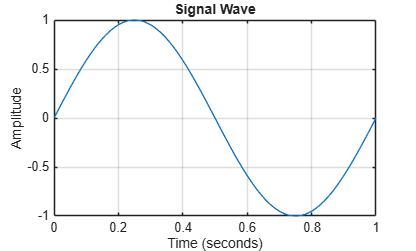

% Time range
time = 0:0.01:1;
% Frequency
freq = 1;
% Signal Data
signal_Data_Sin = 

% Plot
plot();

title("Signal Wave");
xlabel("Time (seconds)");
ylabel("Amplitude");
grid on;

The `hold on` command preserves existing plots when adding new ones, allowing multiple datasets to be overlaid on the same axes for comparison.

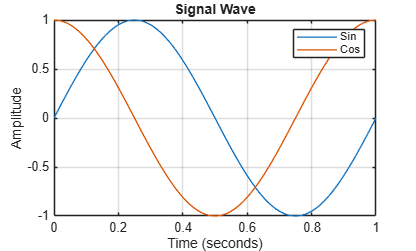

% New Signal Data
signal_Data_Cos = 

% Hold on plot
hold on;
plot();
hold off;
legend("Sin", "Cos");

The `tiledlayout()` function divides a figure into a grid of smaller axes. This is useful for comparing different datasets or viewing the same data at different scales side-by-side. The syntax `tiledlayout(m, n)` creates an m-by-n grid.

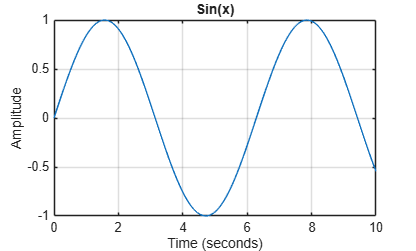

% tiled plots
tiledlayout(2,1);

x3 = linspace(0,10);
y3 = sin(x3);
plot(x3,y3)
grid on;
title("Sin(x)");
xlabel("Time (seconds)");
ylabel("Amplitude");

% next
nexttile

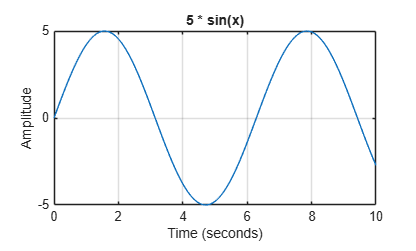

Amp1 = 5;
y4 = Amp1 * sin(x3);
plot(x3,y4)
grid on;
title([num2str(Amp1) ' * sin(x)']) 
xlabel("Time (seconds)");
ylabel("Amplitude");

## 9. Low-Code Tools.

Import and plot data with MATLAB's Low-code tools.

% Import Data


fun_data = 30×2 table
    timesec    amplitude
    _______    _________

       1           0    
       2           0    
       3           1    
       4           1    
       5           0    
       6           0    
       7           1    
       8           1    
       9           0    
      10           0    
      11           1    
      12           1    
      13           0    
      14           0    
      15           1    
      16           1    


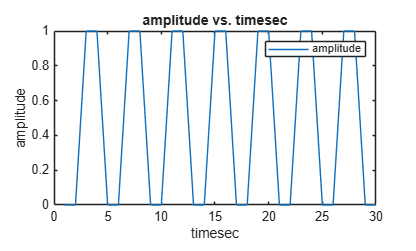


% Plot Data
